# Set Data

load('forclass.mat')
x = 1:64; % size of 1D-image
img = img(150,x)'; 
H1 = GenToeplitz(64,5);
H2 = GenCirculant(64,5);

## Calculate SVF

[V1,D1,U1t] = svd(H1);
[V2,D2,U2t] = svd(H2);

## Plot

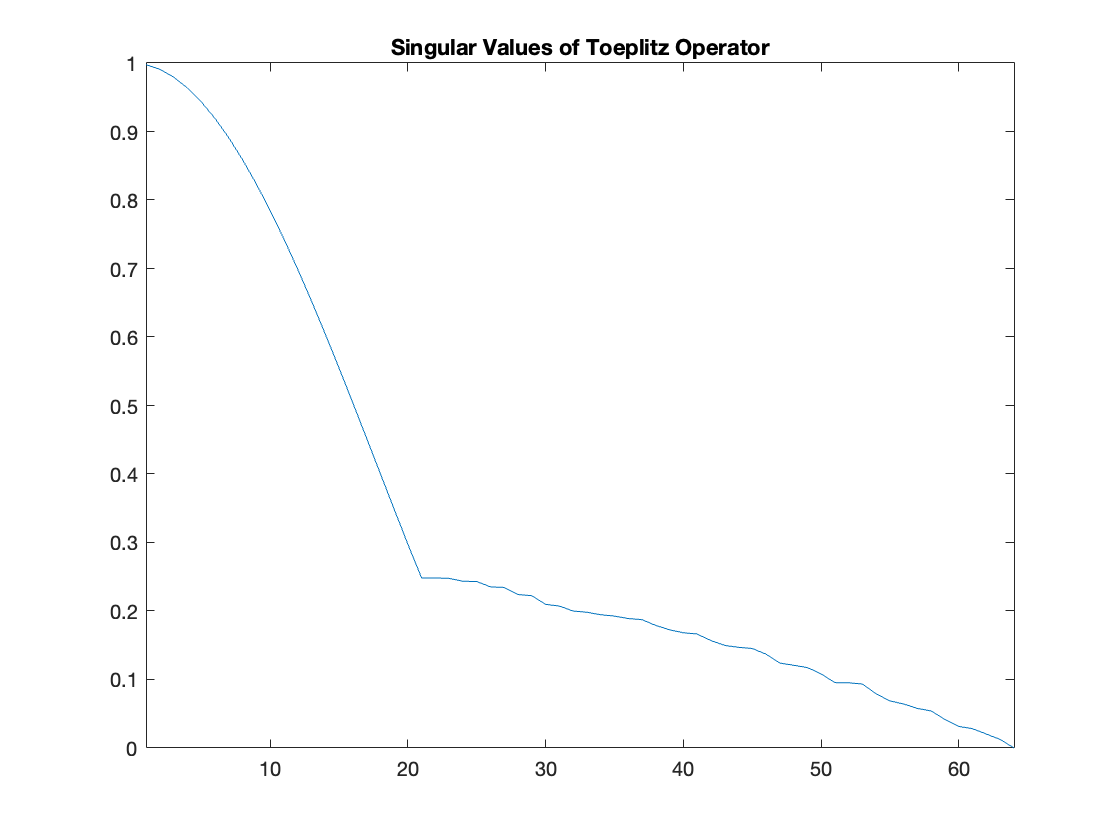

%Plot S(D)
figure('Color', 'w')
plot(x,diag(D1))
title('Singular Values of Toeplitz Operator')
xlim([1 64])

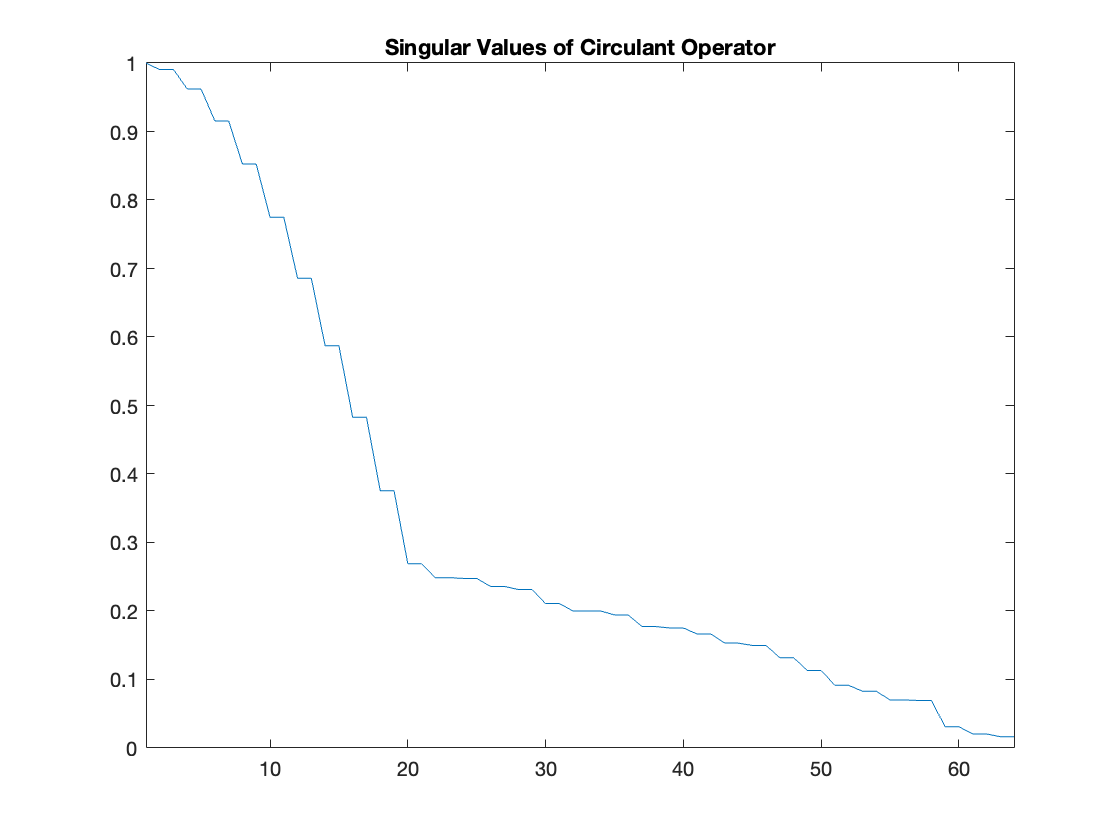


figure('Color', 'w')
plot(x,diag(D2))
title('Singular Values of Circulant Operator')
xlim([1 64])

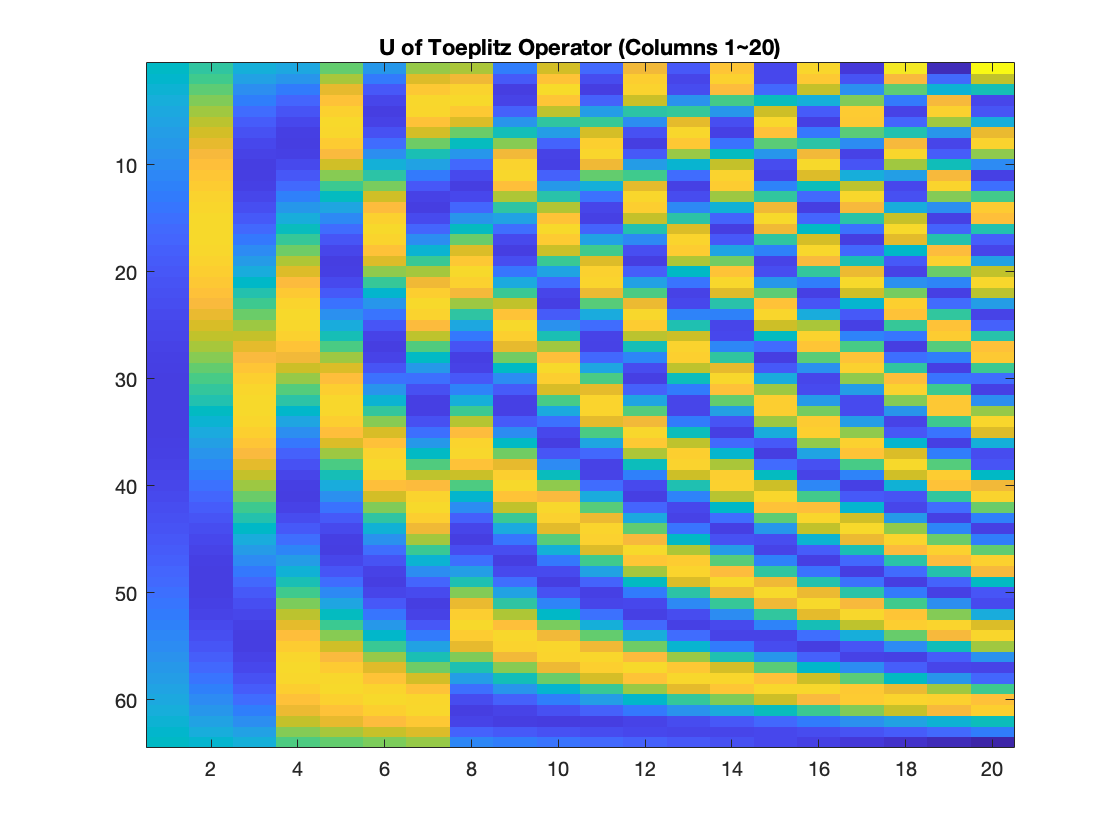


% Plot U
figure('Color', 'w')
imagesc(U1t(:,1:20))
title('U of Toeplitz Operator (Columns 1~20)')

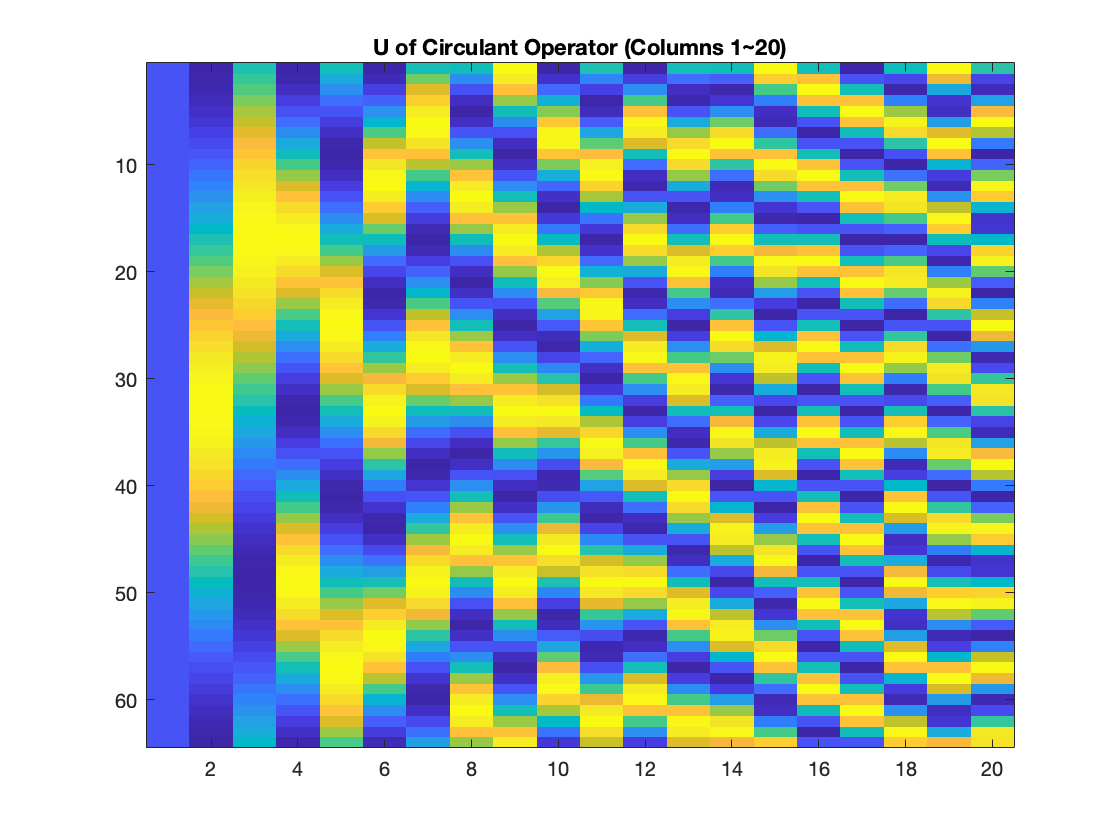


figure('Color', 'w')
imagesc(U2t(:,1:20))
title('U of Circulant Operator (Columns 1~20)')

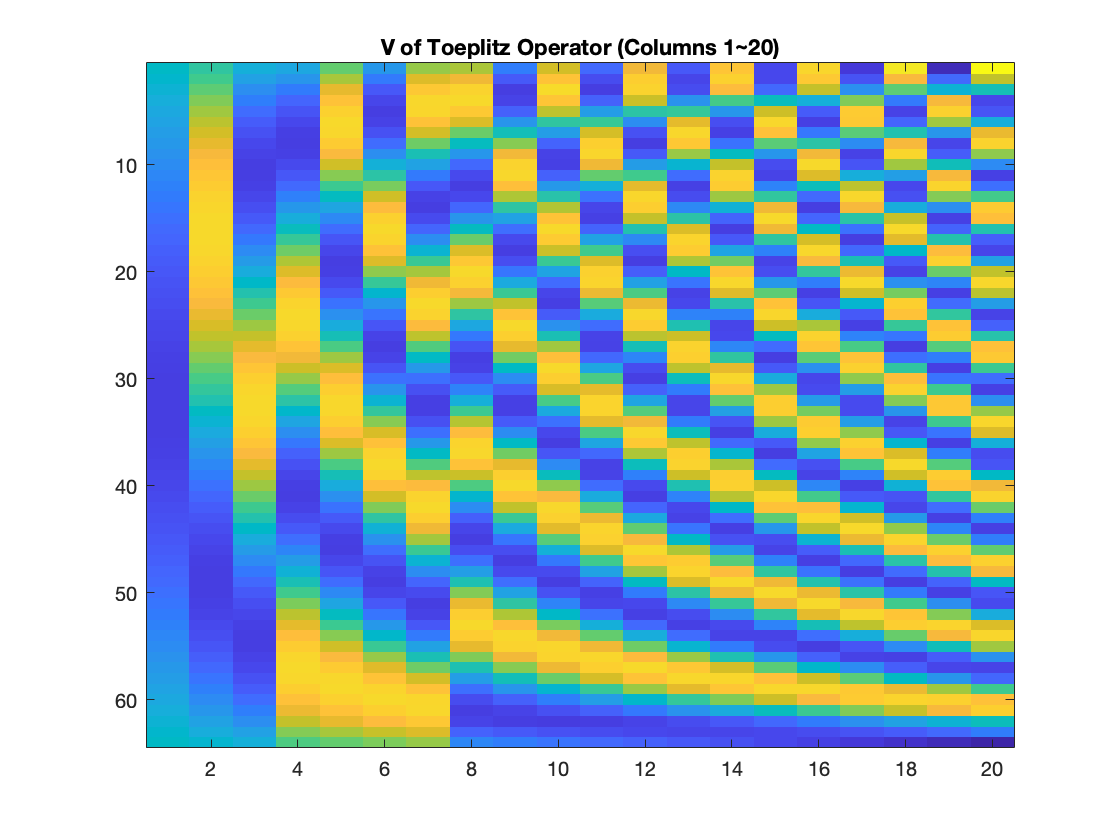


% Plot V
figure('Color', 'w')
imagesc(V1(:,1:20))
title('V of Toeplitz Operator (Columns 1~20)')

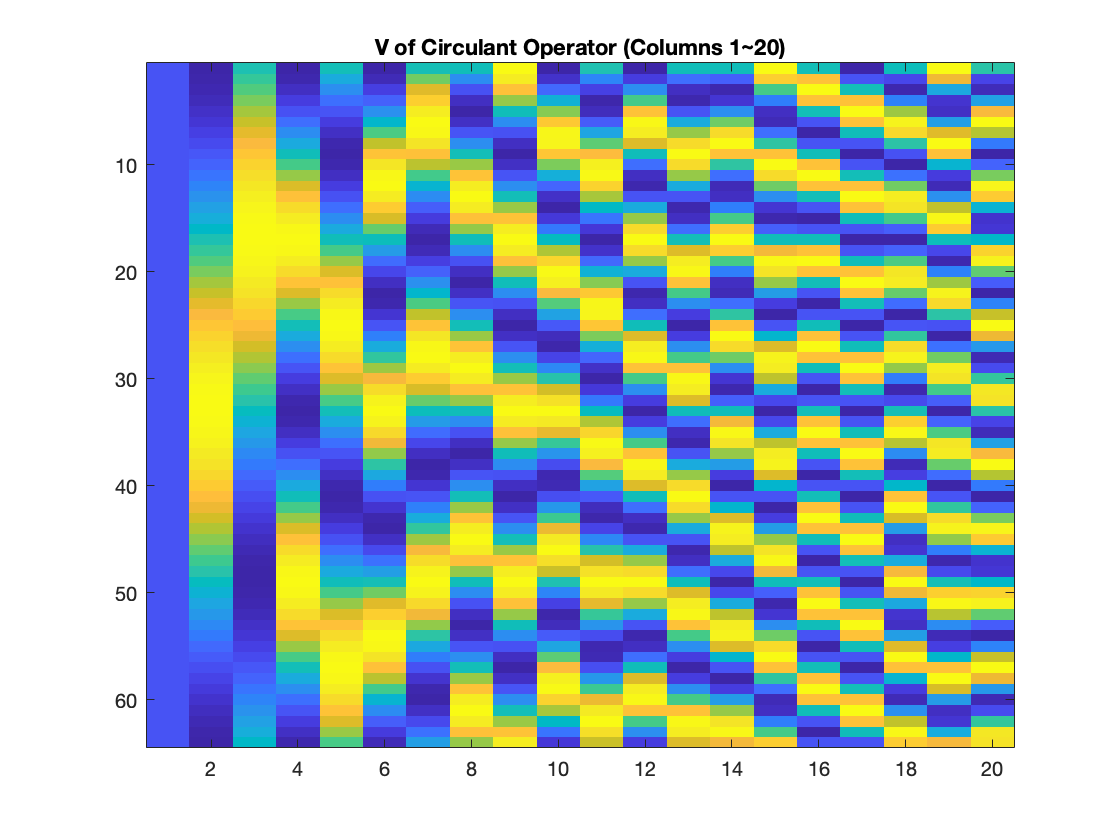


figure('Color', 'w')
imagesc(V2(:,1:20))
title('V of Circulant Operator (Columns 1~20)')